# Stima in frequenza 

L'obiettivo è stimare la risposta in frequenza andando a inserire un segnale eccitante attorno a un punto di equilibrio.

Il segnale eccitante deve un contenuto frequenziale nella banda dove ci interessa stimare.

## Definizione punto di equlibrio

Visto che la realtà non è lineare, la stima vale solo attorno ad un punto di equilibrio. Nel nostro sistema le maggiori nonlinearità sono

- le saturazioni (dobbiamo starci lontano)

- l'attrito statico, stimiamo il sistema con una velocità sempre diversa da zero. In molte macchine, occorre tenere presente i limiti di giunto. In quel caso si può aggiungere una portante in bassa frequenza 


clear all;close all;clc;
motorecarico_2

mdl = 'StimaFrenquenza_2';
open_system(mdl)

Selezionare i punti di ingresso e uscita (vedi schema simulink)

io=getlinio(mdl);

Calcola il punto di equilibrio del sistema (attendo 20 secondi per esaurire il transitorio)

operationg_point=findop(mdl,20);

## Calcolo segnale eccitante

il segnale eccitante scelto è una serie di sinusoidi

Le sinusoidi devono avere frequenza inferiore alla frequenza di Nyquist

st=1e-3;
wmax=pi/st

wmax = 3.1416e+03

è consigliabile avere più sinusoidi nella zona a bassa frequenza e dove ci sono le risonanze (si può fare una prima stima veloce per capire dove sono i range d'interesse)

Le sinusoidi a bassa frequenza hanno periodi lunghi (ovviamente!) per cui il sistema riesce a terminare il transitorio già dopo un periodo, e bastano pochi periodi per avere tanti dati.

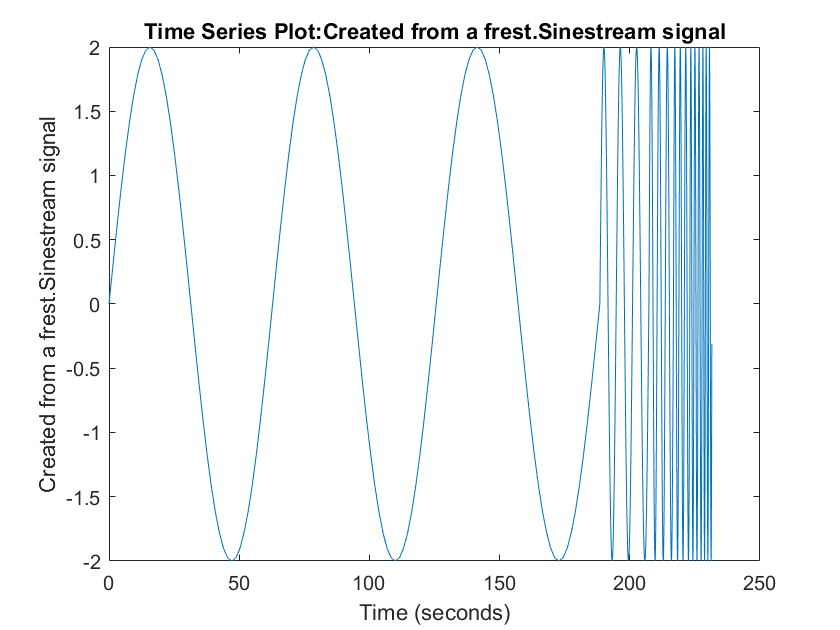

freqs1 = [0.1 1 2 3 4 5]'; % frequenze 
amps1 = 2*ones(length(freqs1),1); % ampiezza
ramp1 = 0*ones(length(freqs1),1); % numero di sinusoidi "a rampa" (durante la rampa l'ampiezza cresce da 0 al valore specificato)
settle1 = 0*ones(length(freqs1),1); % numero sinusoidi di assestamento "da scartare"
pds1 = 3*ones(length(freqs1),1); % numero di sinusoidi

input = frest.Sinestream('Frequency',freqs1,...
    'Amplitude',amps1,...
    'RampPeriods',ramp1,...
    'SettlingPeriods',settle1,...
    'NumPeriods',pds1);
figure
plot(input)

Nel range di media frequenza posso usare più periodi, e posso infittire i dati attorno alle frequenze di risonanza/antirisonanza spaziando le frequenze in scala logaritmica

freqs2 =logspace(log10(6),log10(100),100)'; % freq. spaziate logaritmicamente
amps2 = 2*ones(length(freqs2),1);
ramp2 = 0*ones(length(freqs2),1);
settle2 = 0*ones(length(freqs2),1);
pds2 = 4*ones(length(freqs2),1);

Ad alta frequenza posso dare una spazzolata spaziando le frequenze in scala logaritmica, può essere consigliato ridurre l'ampiezza del segnale per non far saturare gli attuatori

freqs3 = logspace(log10(120),log10(wmax),20)'; % freq. spaziate logaritmicamente

amps3 = 2*ones(length(freqs3),1);
ramp3 = 2*ones(length(freqs3),1);
settle3 = 2*ones(length(freqs3),1);
pds3 = 5*ones(length(freqs3),1);

Il segnale complessivo è dato dalla somma delle varie sinusoidi

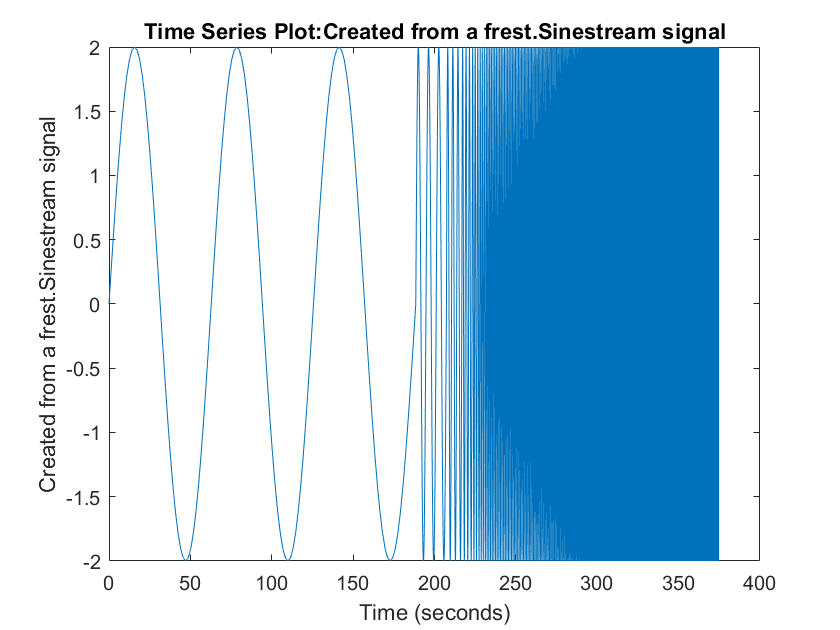

freqs=[freqs1;freqs2;freqs3];
amps=[amps1;amps2;amps3];
ramp=[ramp1;ramp2;ramp3];
settle=[settle1;settle2;settle3];
pds=[pds1;pds2;pds3];
input = frest.Sinestream('Frequency',freqs,...
    'Amplitude',amps,...
    'RampPeriods',ramp,...
    'SettlingPeriods',settle,...
    'NumPeriods',pds);
figure
plot(input)

é possibile utilizzare anche altri segnali come la[ pseudorandom binary sequence](https://en.wikipedia.org/wiki/Pseudorandom_binary_sequence), il [chirp](https://it.wikipedia.org/wiki/Chirp), o la somma di molte sinuosoidi che permettono di fare esperimenti brevi. Tuttavia la spazzolata di sinuosoidi usata in questo caso permette di avere i dati della risposta in frequenza frequenza per frequenza, ottenendo spesso migliori risultati.

## Esperimento

simuliamo il sistema attorno al punto di equilibrio con il segnale eccitante

[sysest,simout] = frestimate(mdl,operationg_point,io,input);

sysest è la risposta in frequenza calcolata, simout è l'output completo della simulazione.

## Risultati e uso della risposta in frequenza

L'esperimento consente di ottenere la risposta in frequenza (una stima della risposta in frequenza!), che può essere usata così com'è per le tarature che non richiedono la conoscenza della funzione di trasferimento (loop shaping, ottimizzazione).

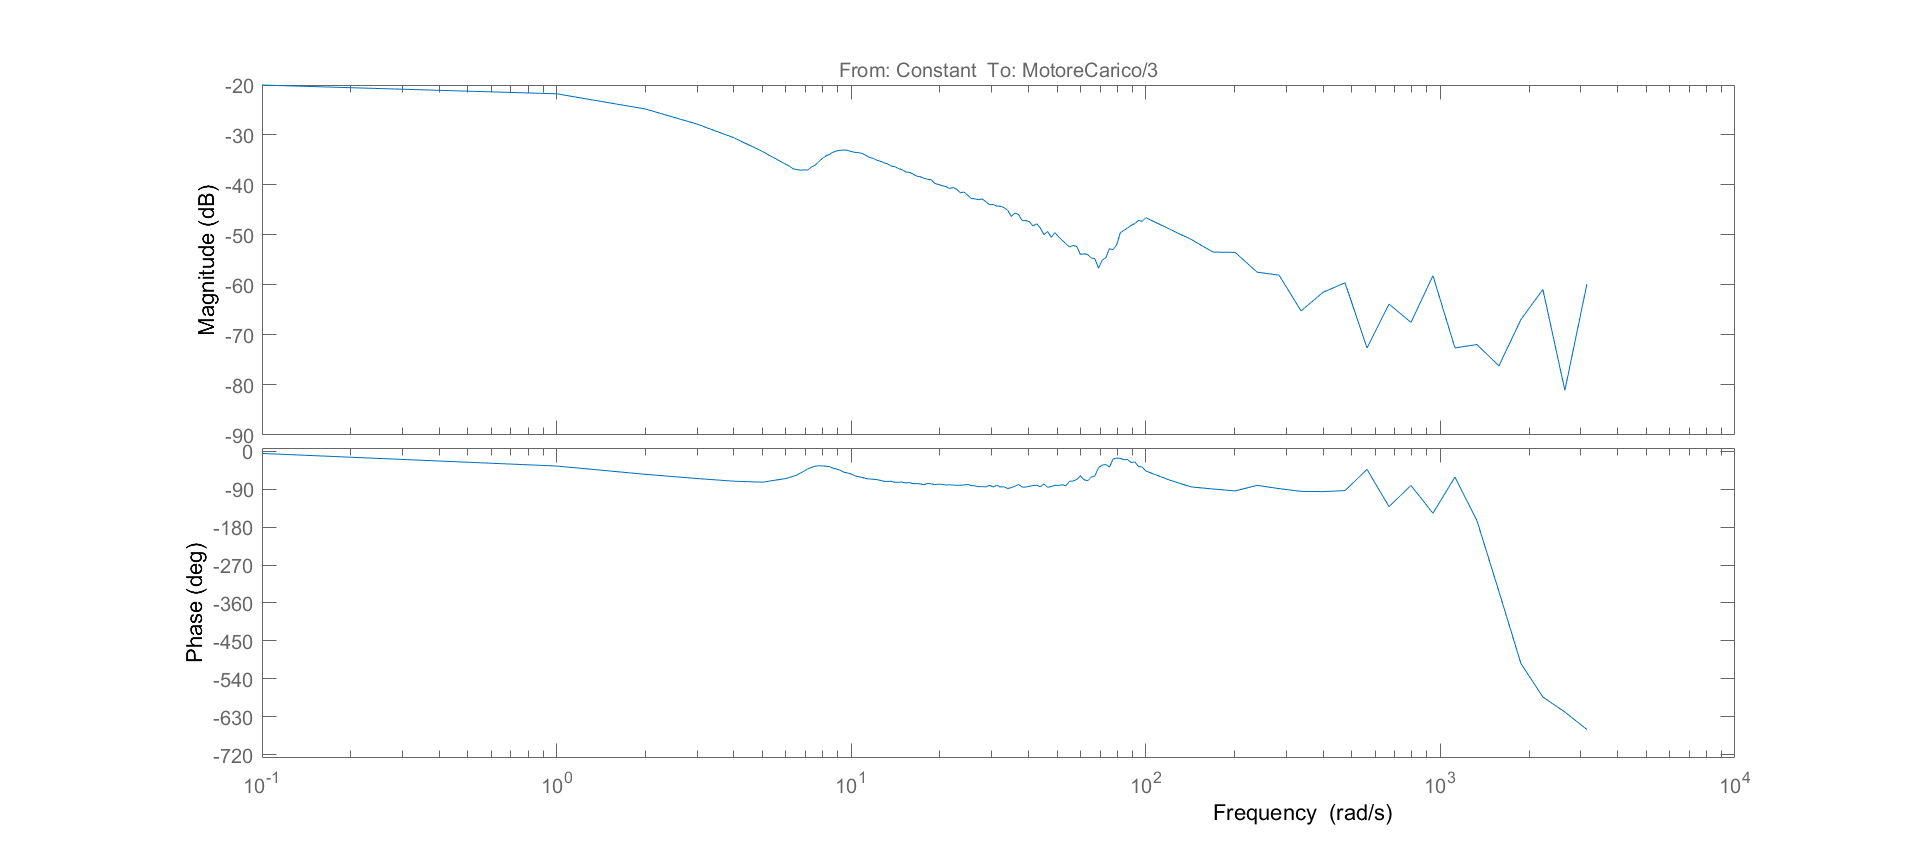

figure('Position',[1 1 1800 800])
bode(sysest)

## Stima del modello

data la risposta in frequenza, possiamo stimare il modello del sistema.

Esistono diversi tool, dal semplice "mettere i poli e gli zeri a mano" a tool automatizzati. Le linee guida sono sempre: 

- più il modello è semplice meglio è

- validare il risultato!

Scegliendo *ssest*, posso stimare il sistema usando:

modello_stimato=ssest(sysest)


modello_stimato =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
               x1          x2          x3
   x1      -1.969       8.094  -2.634e-09
   x2      -8.094      -1.969       3.169
   x3   3.047e-07  -2.447e-07      -1.418
 
  B = 
         Constant
   x1  -5.524e-08
   x2  -4.116e-08
   x3         0.5
 
  C = 
                      x1       x2       x3
   MotoreCarico   -0.251  -0.1854   0.3939
 
  D = 
                 Constant
   MotoreCarico         0
 
  K = 
       MotoreCarico
   x1             0
   x2             0
   x3             0
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: none
   Number of free coefficients: 15
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using SSEST on frequency response data "sysest".


che mi stima un sistema con ordine

order(modello_stimato)

ans = 3

e mette i poli e li zeri:

zpk(modello_stimato)


ans =
 
  From input "Constant" to output "MotoreCarico/3":
   0.19694 (s^2 + 2.446s + 50.11)
  --------------------------------
  (s+1.418) (s^2 + 3.937s + 69.39)
 
Continuous-time zero/pole/gain model.



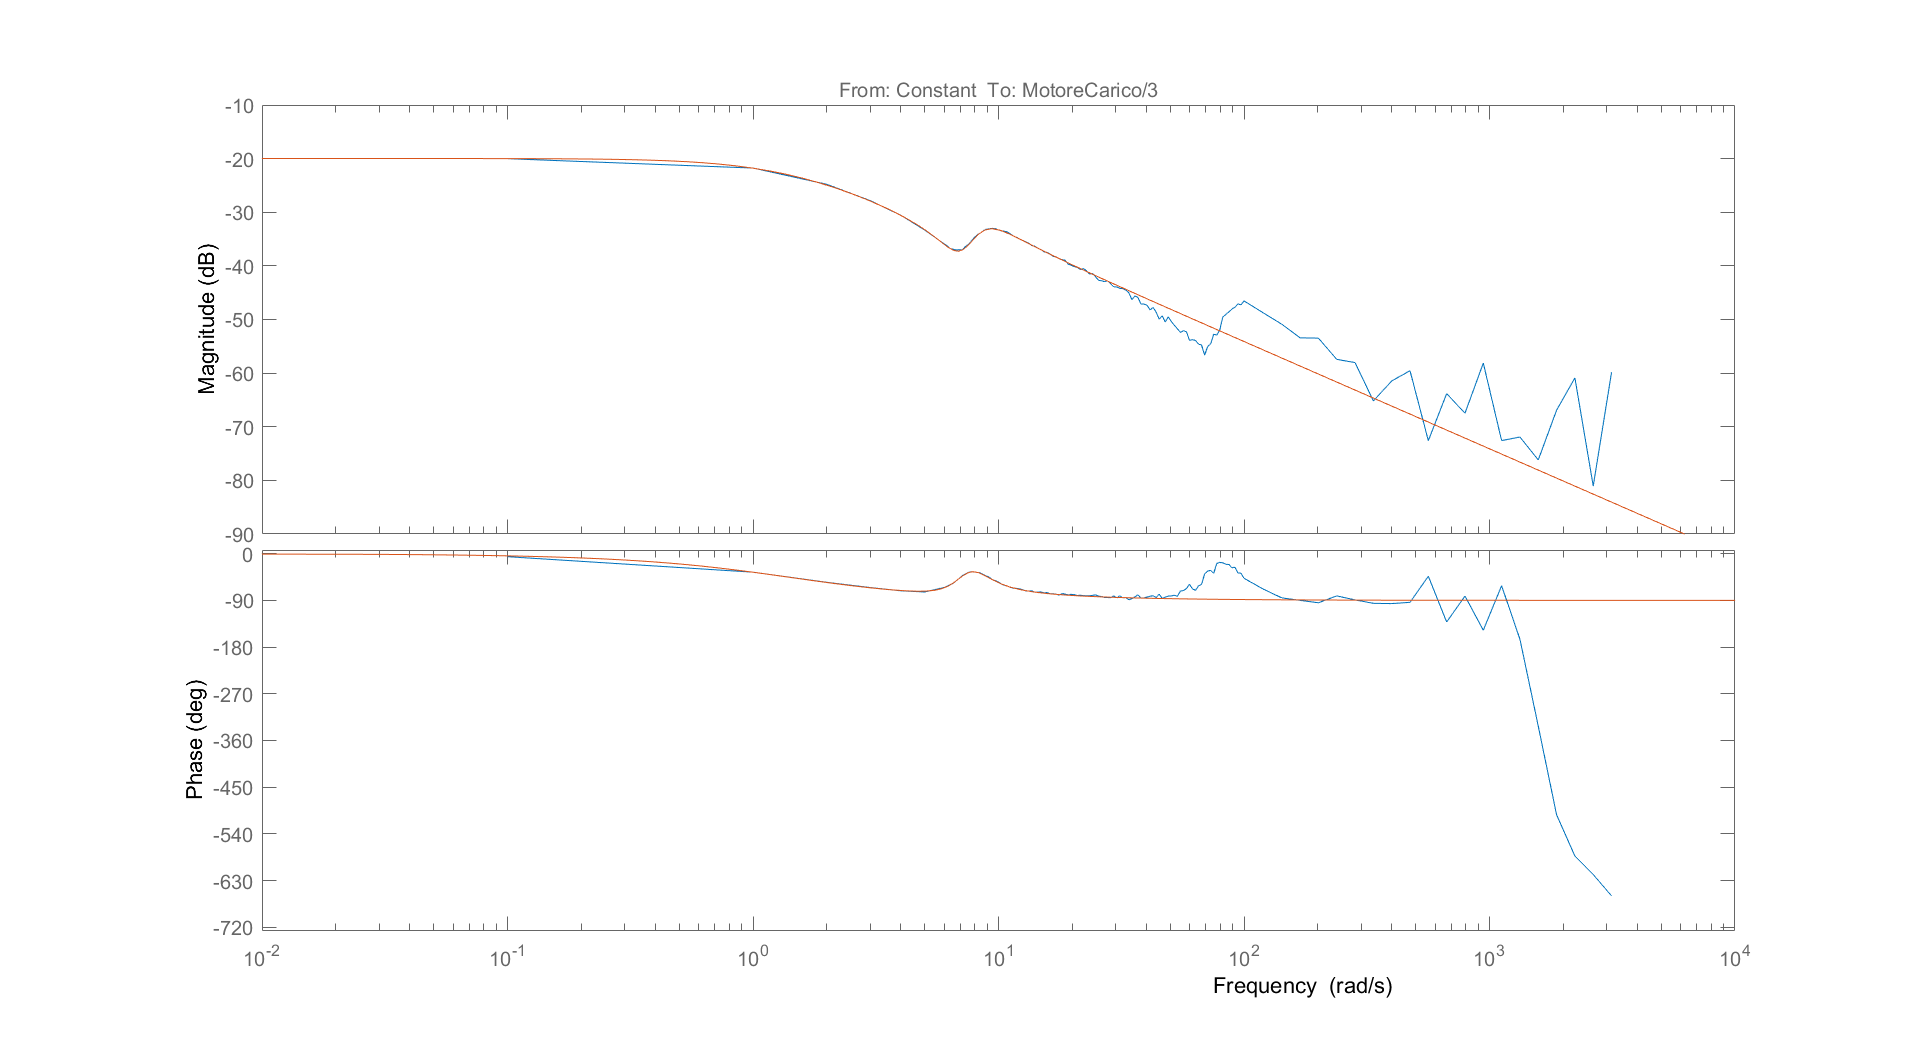

figure('Position',[1 1 1800 800])
bode(sysest,modello_stimato)

Ragionamo  sulla risposta del sistema

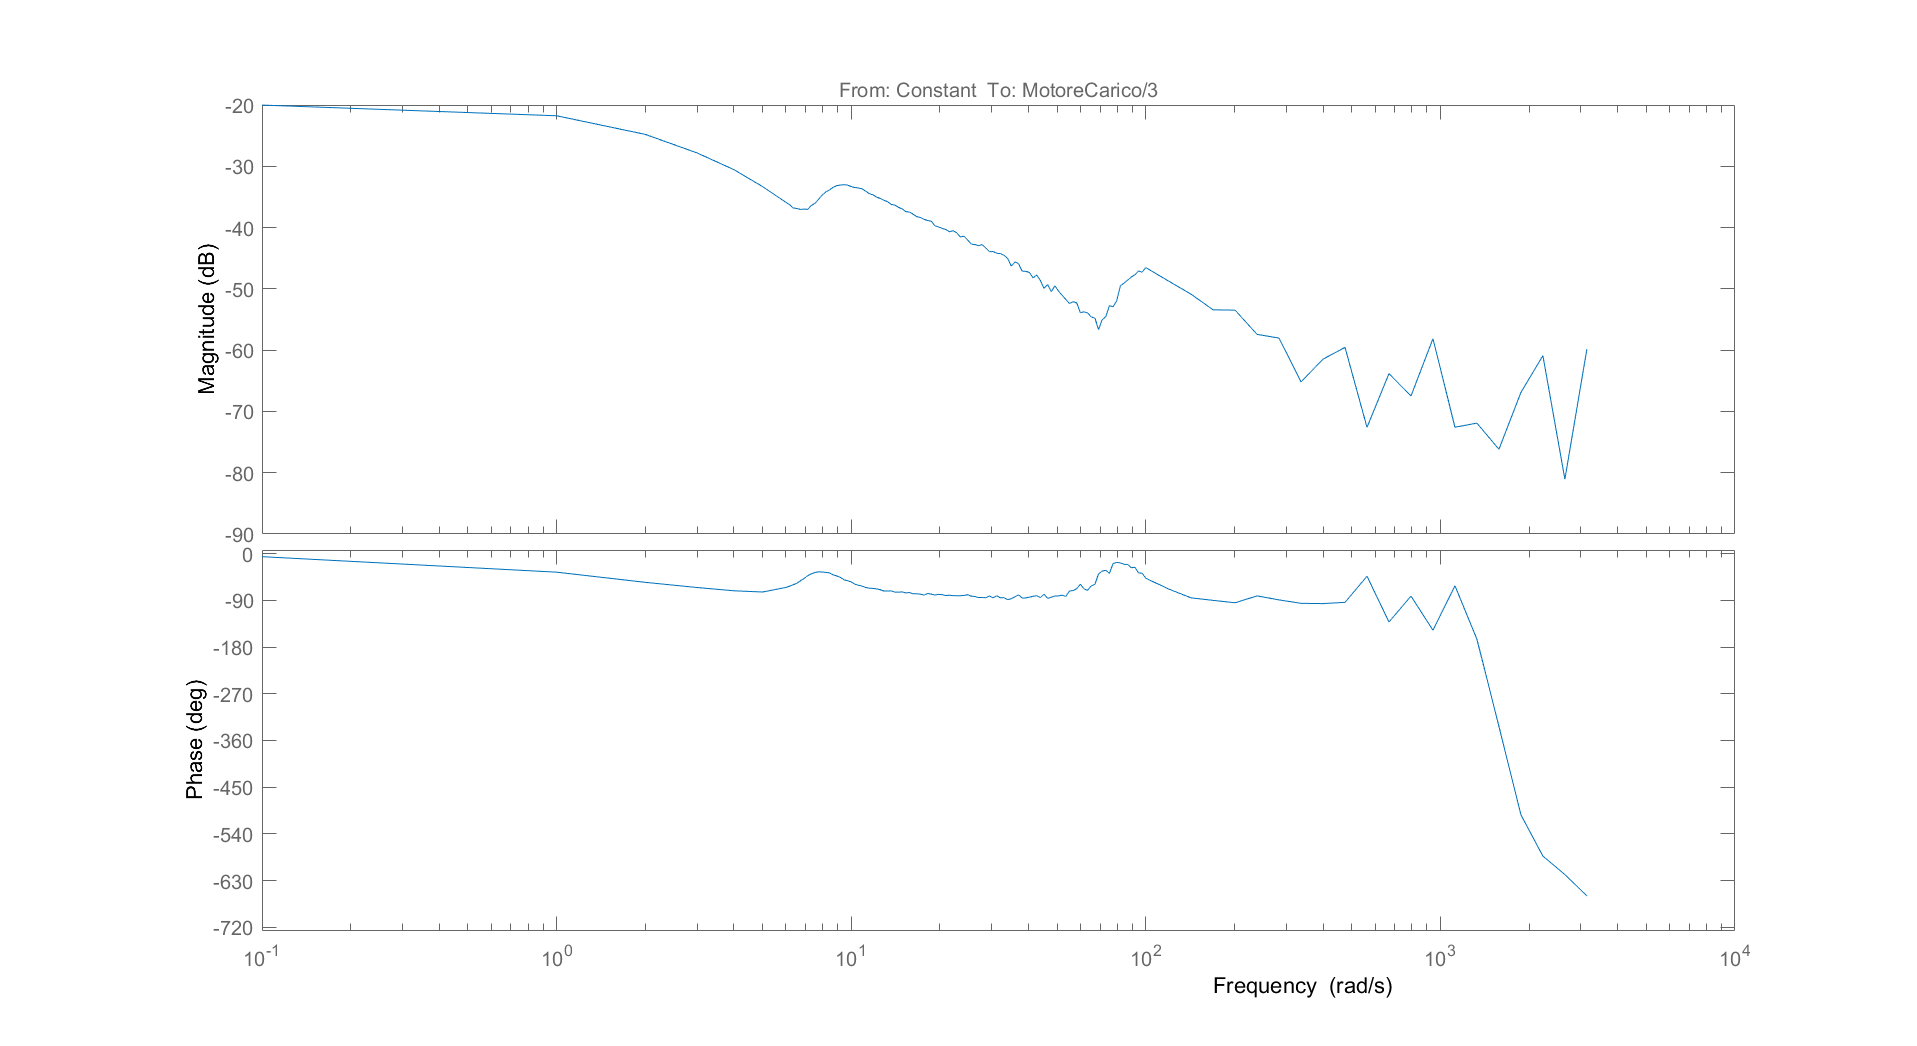

figure('Position',[1 1 1800 800])
bode(sysest)

ha due coppie poli complessi coniugati / zeri complessi coniugati (il "filtro" notch attorno a 70-100 rad/s), e (almeno) un polo in bassa frequenza

Scelgo quindi un sistema di ordine 5

modello_5_ordine_stimato=ssest(sysest,5);

che mi stima un sistema con ordine

order(modello_5_ordine_stimato)

ans = 5

e mette i poli e li zeri:

zpk(modello_5_ordine_stimato)


ans =
 
  From input "Constant" to output "MotoreCarico/3":
  0.32964 (s^2 + 2.487s + 49.78) (s^2 + 22.51s + 5126)
  -----------------------------------------------------
  (s+1.435) (s^2 + 4.046s + 69.4) (s^2 + 35.83s + 8409)
 
Continuous-time zero/pole/gain model.



Possiamo vedere come le due risposte siano strutturalmente simili.

Anche analizzando la risposta in frequenza

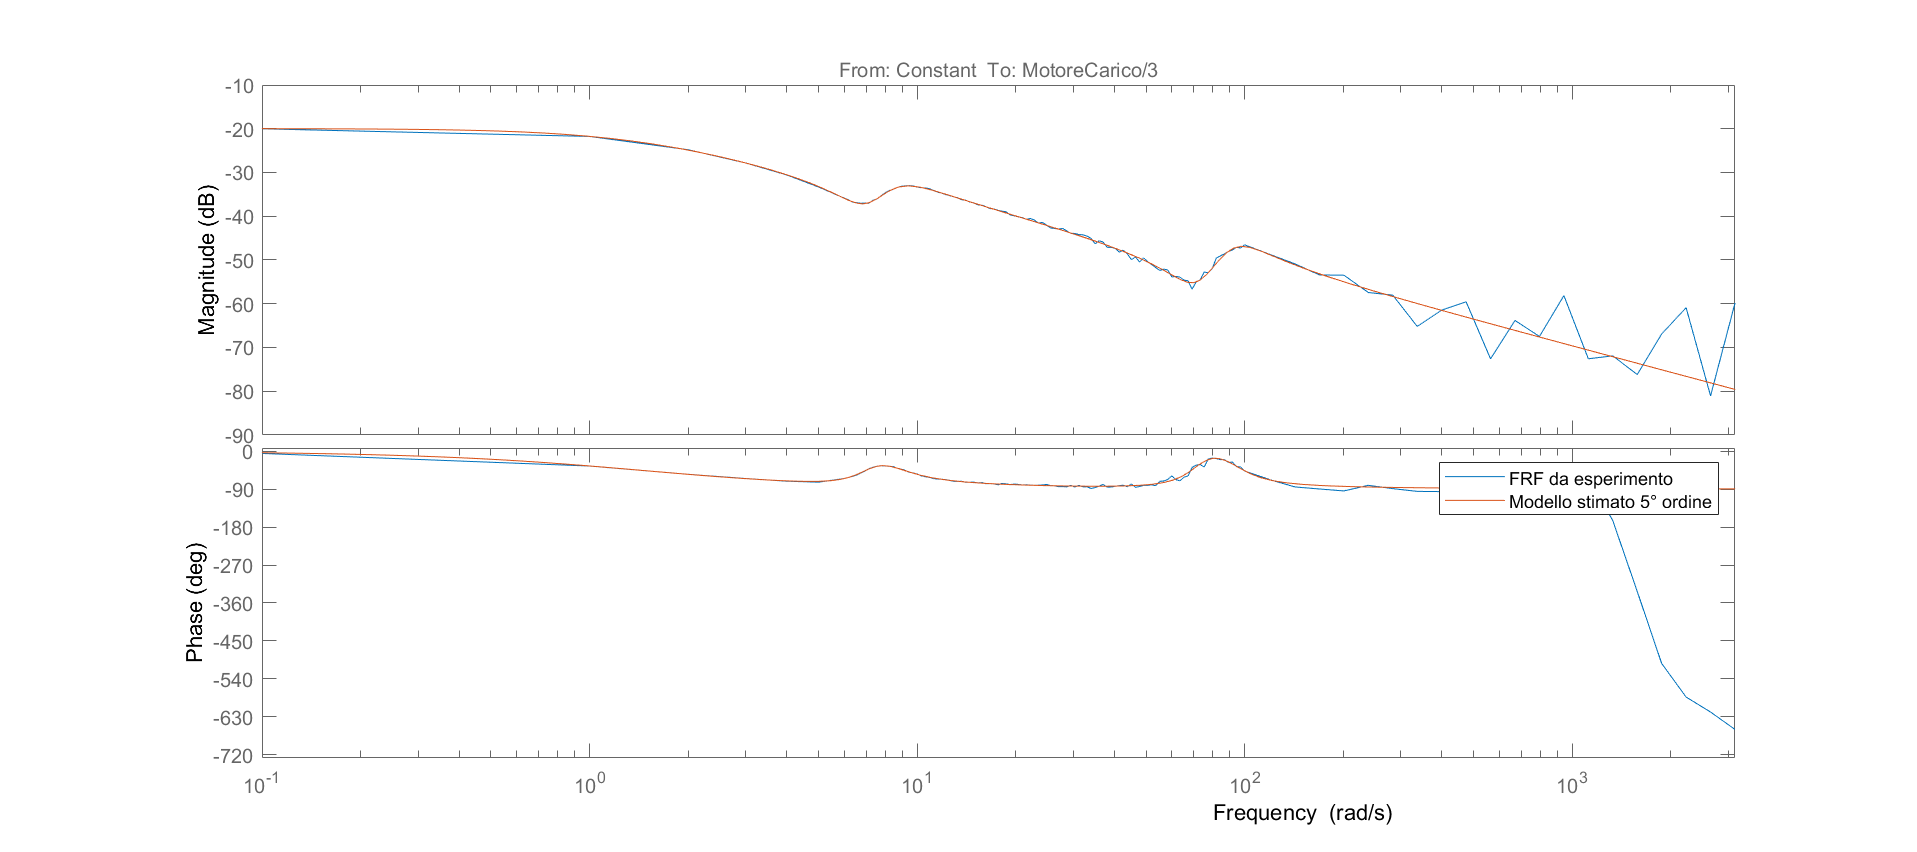

figure('Position',[1 1 1800 800])
bode(sysest,modello_5_ordine_stimato)
legend('FRF da esperimento','Modello stimato 5° ordine')
xlim([min(freqs) max(freqs)])

le risposte sono molto simili, bisogna considerare che:

- il modello lineare non tiene conto dell'attrito e del rendimento del riduttore, che "smorzano" le oscillazioni

- la risposta in frequenza acquisita è campionata, quindi ad alta frequenza abbiamo l'effetto della discretizzazione

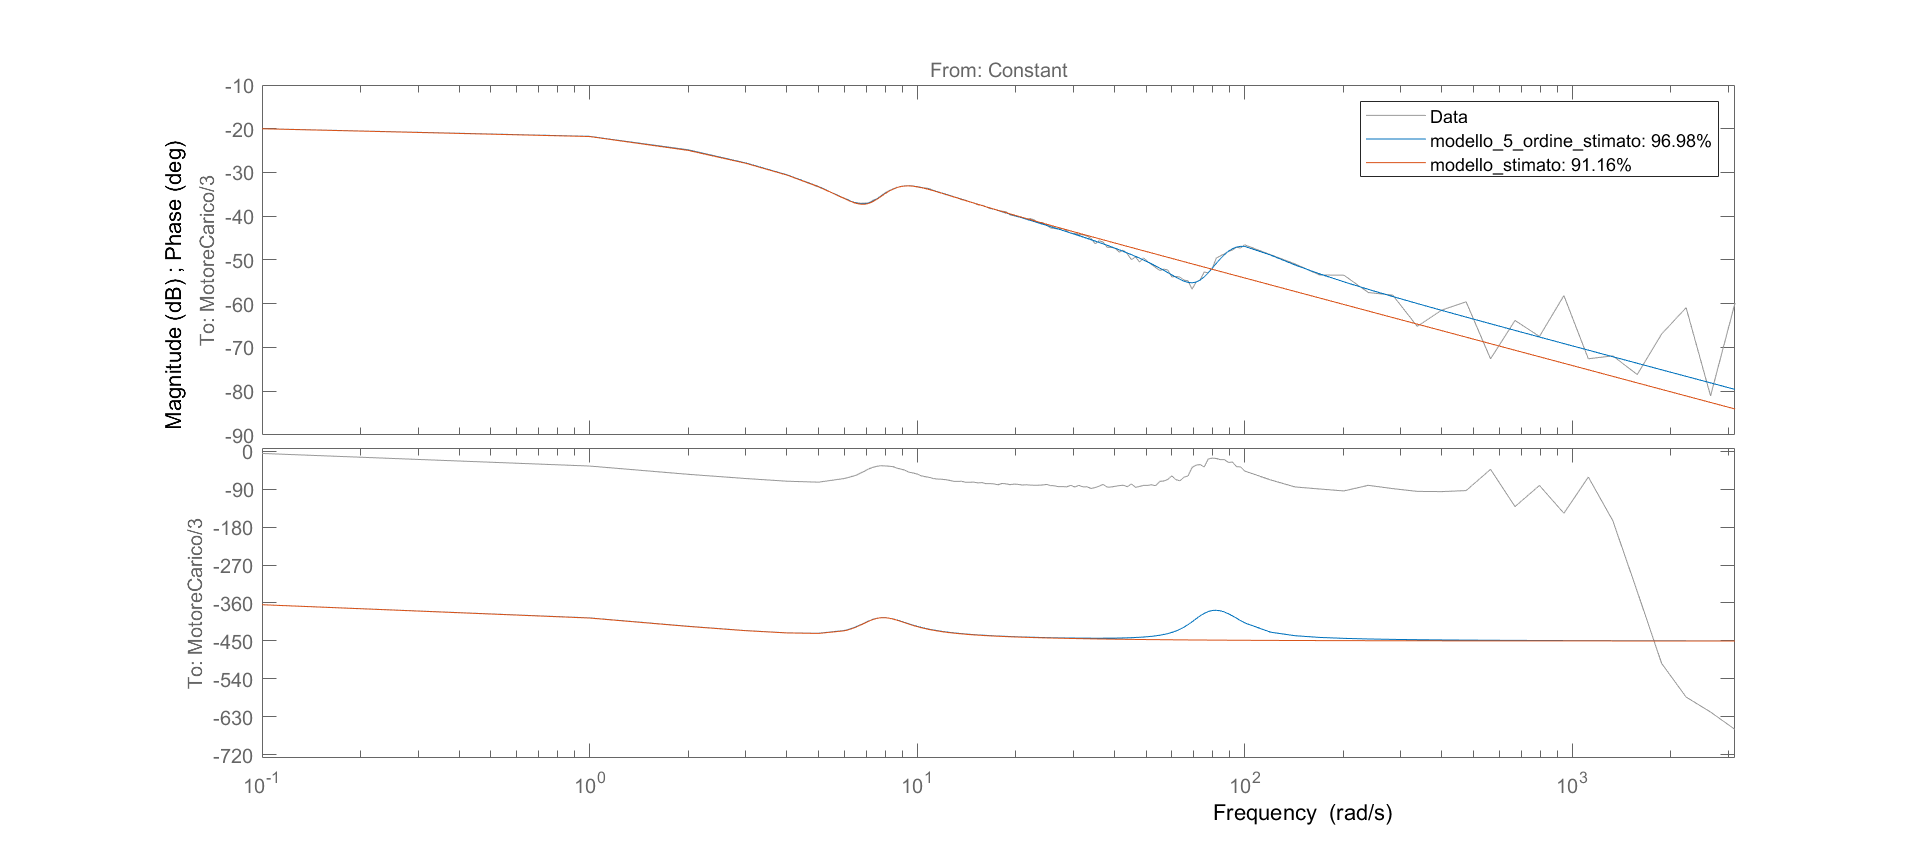

figure('Position',[1 1 1800 800])
compare(sysest,modello_5_ordine_stimato,modello_stimato)

## Validazione!

Creaiamo un altro segnale con frequenza e ampiezze diverse:

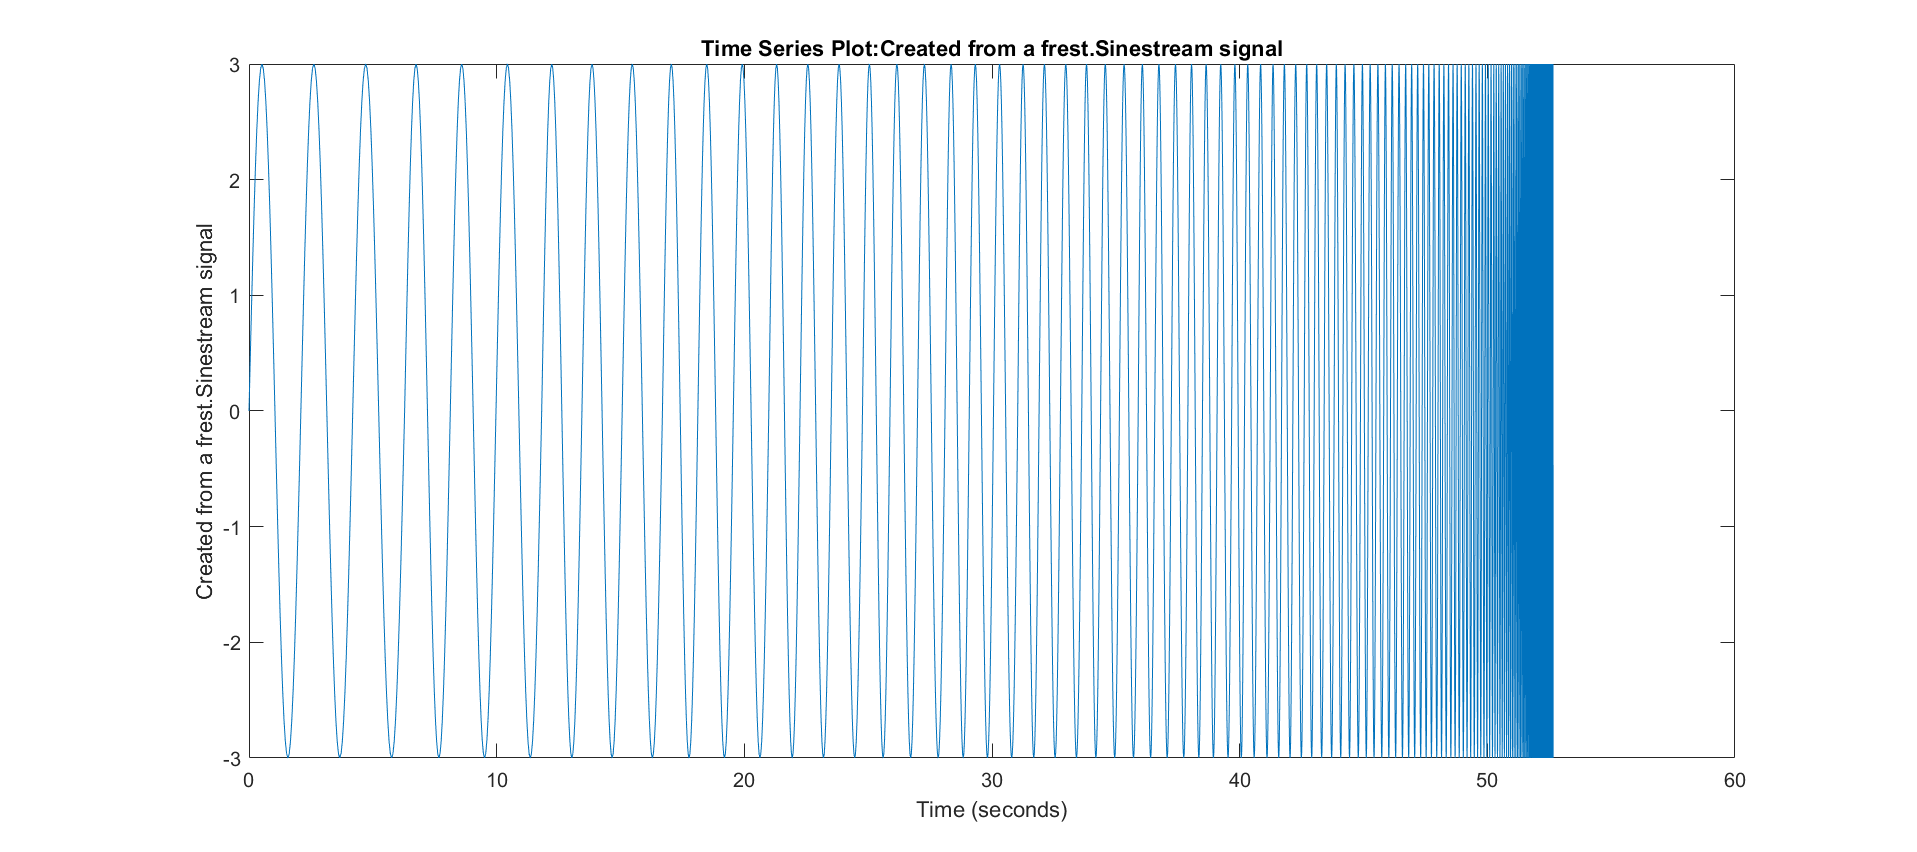

freqs_val1 = logspace(log10(3),log10(1500),50)';
amps_val1 = 3*ones(length(freqs_val1),1);
ramp_val1 = 0*ones(length(freqs_val1),1);
settle_val1 = 0*ones(length(freqs_val1),1);
pds_val1 = 3*ones(length(freqs_val1),1);

input_val = frest.Sinestream('Frequency',freqs_val1,...
    'Amplitude',amps_val1,...
    'RampPeriods',ramp_val1,...
    'SettlingPeriods',settle_val1,...
    'NumPeriods',pds_val1);

figure('Position',[1 1 1800 800])
plot(input_val)

[sys_val,simout_val] = frestimate(mdl,operationg_point,io,input_val);

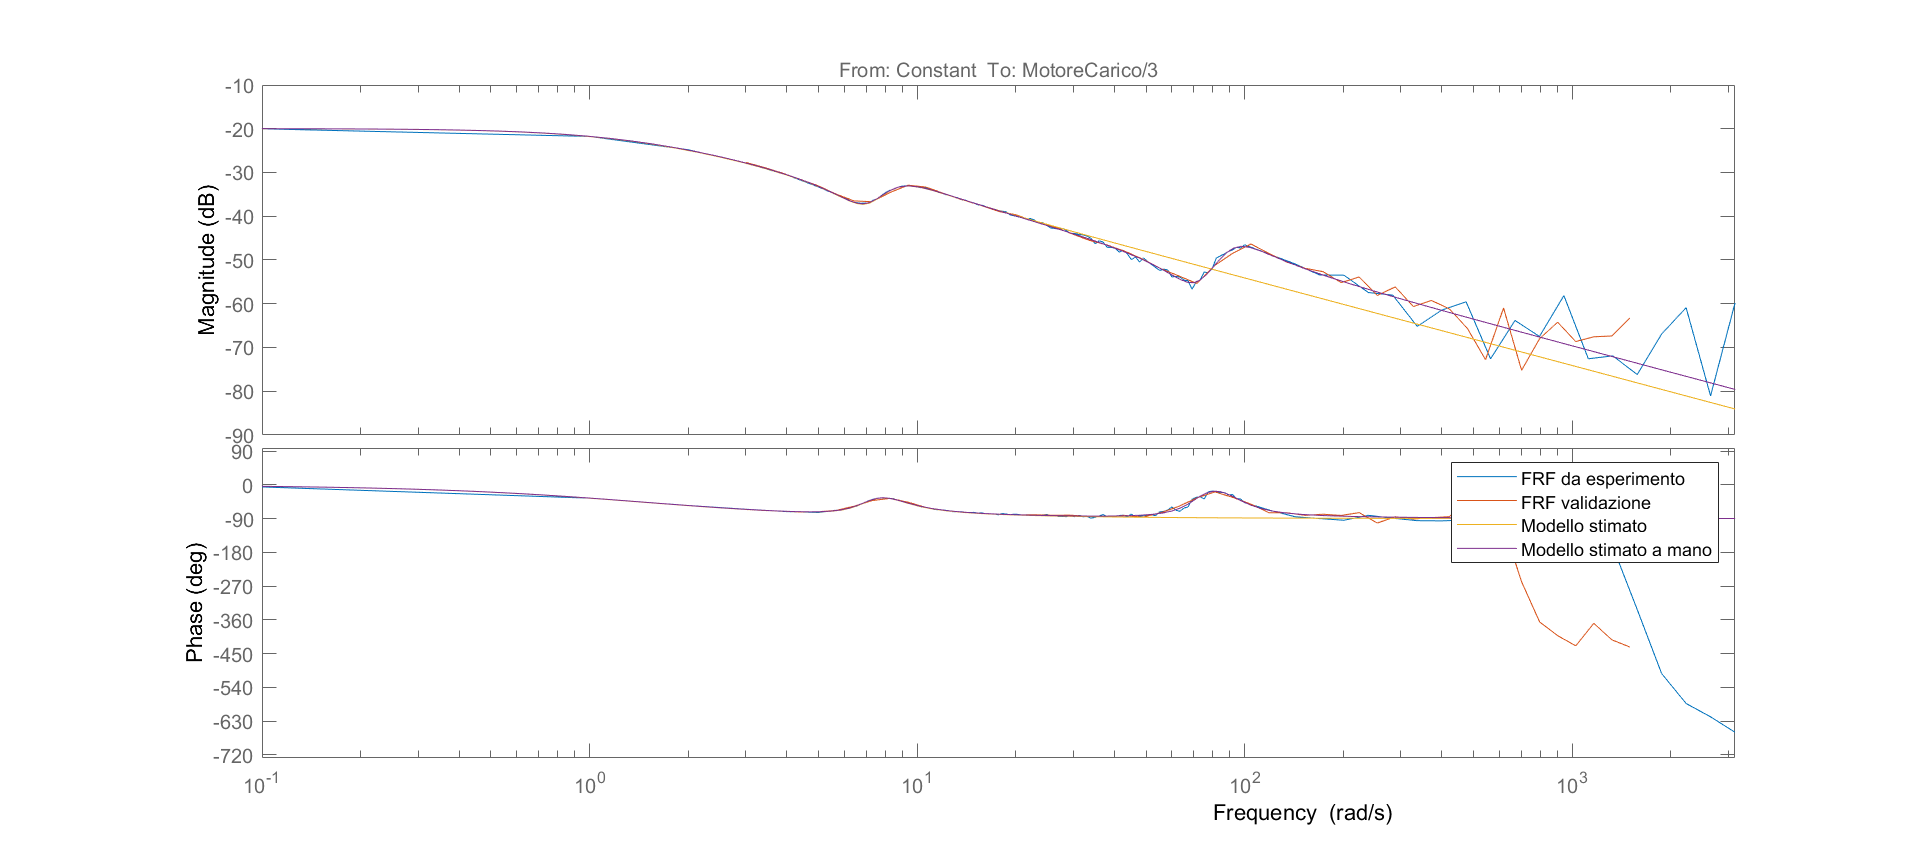

figure('Position',[1 1 1800 800])
bode(sysest,sys_val,modello_stimato,modello_5_ordine_stimato)
legend('FRF da esperimento','FRF validazione','Modello stimato','Modello stimato a mano')
xlim([min(freqs) max(freqs)])

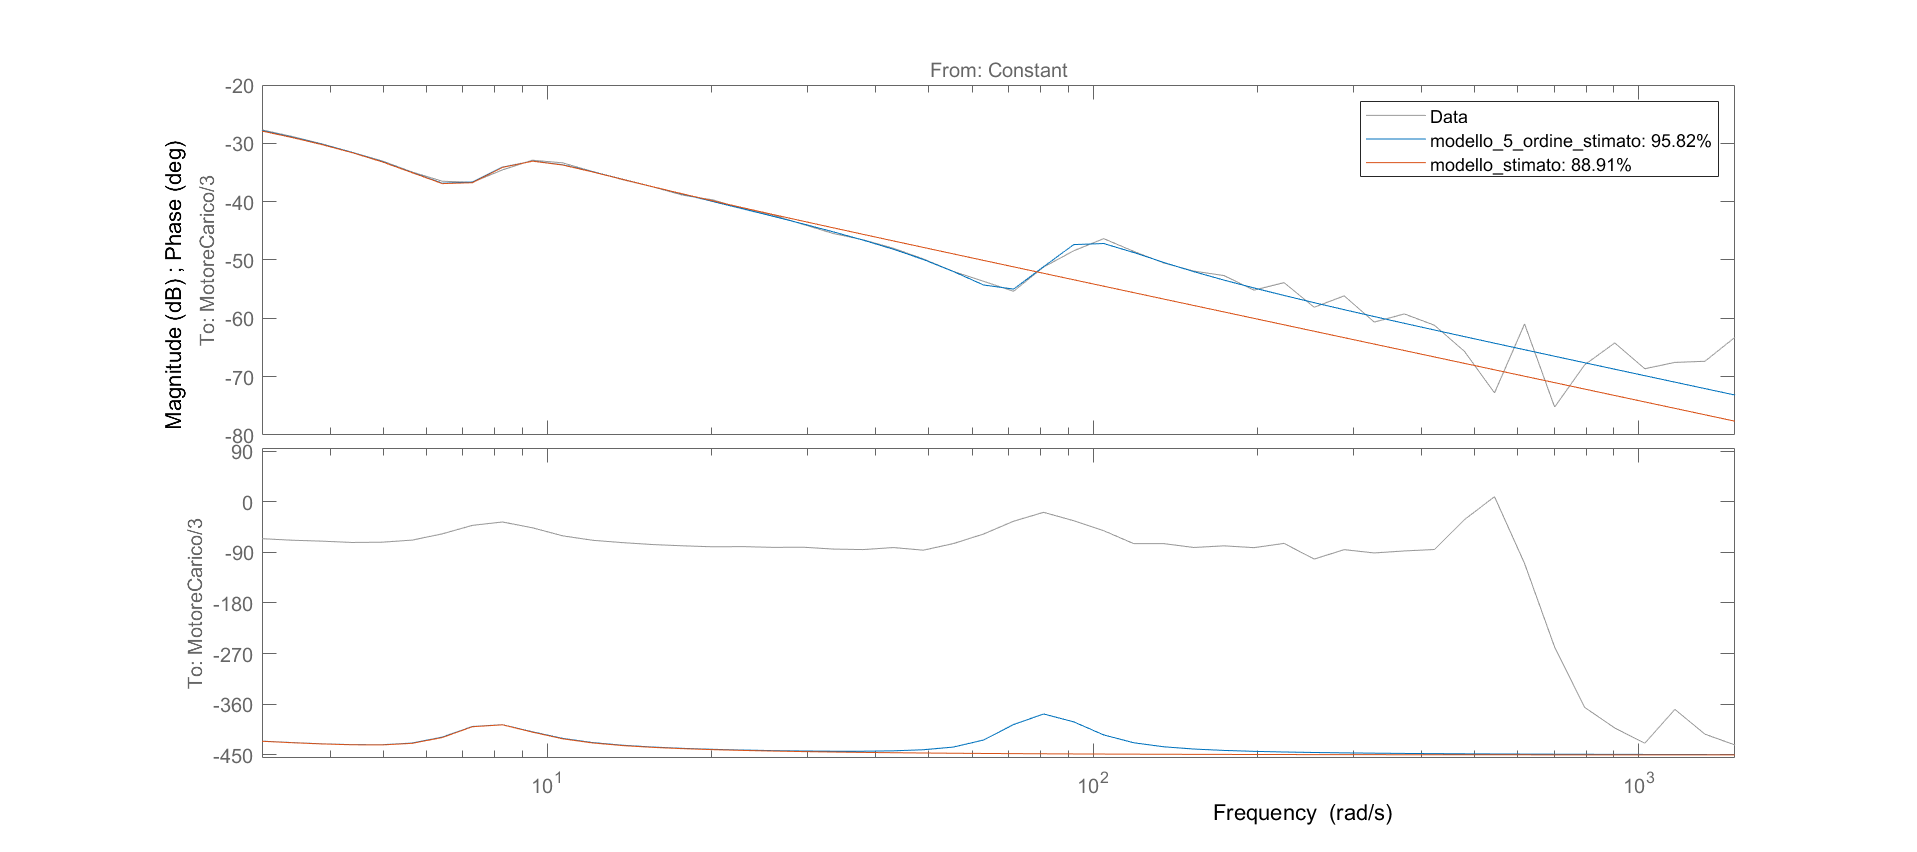

figure('Position',[1 1 1800 800])
compare(sys_val,modello_5_ordine_stimato,modello_stimato)